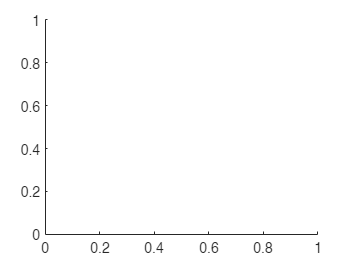

% syms s t;
s = tf('s');
hold off 


student_num = [3 8 1 1 3 5 4 4];
% student_num = [9 3 4 5 3 5 5 3];

sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

zeros_natural = (s+(2*sn_B));
poles_natural = (s+(4*sn_E))*(s+(3*sn_C))*(s+sn_A)*(s+(3i*sn_D)+3*sn_C)*(s-(3i*sn_D)+3*sn_C);
sys_natural = zeros_natural/poles_natural

sys_natural =
 
                              s + 36
  --------------------------------------------------------------
  s^5 + 164 s^4 + 11467 s^3 + 421938 s^2 + 7.616e06 s + 4.859e07
 
Continuous-time transfer function.



adjusted_k = dcgain(sys_natural);

zeros = (s+(2*sn_B));
complex_poles = (s+(3i*sn_D)+3*sn_C)*(s-(3i*sn_D)+3*sn_C)

complex_poles =
 
  s^2 + 66 s + 2178
 
Continuous-time transfer function.



poles = adjusted_k*sn_F*(s+(4*sn_E))*(s+(3*sn_C))*(s+sn_A)*complex_poles;

oltf = minreal(zeros/poles)

oltf =
 
                         8.998e04 s + 3.239e06
  -------------------------------------------------------------------
  s^5 + 164 s^4 + 1.147e04 s^3 + 4.219e05 s^2 + 7.616e06 s + 4.859e07
 
Continuous-time transfer function.




CF = 3*sn_C/2;

H = 2*CF/(s+2*CF);

G = oltf/H; 

% these should be equal!
k = dcgain(oltf)

k = 0.0667

ref = 1/sn_F % value it should be

ref = 0.0667

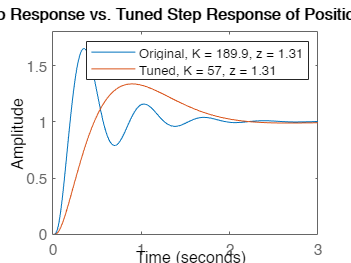


% TF = KG/(1+KGH)
% KGH = KG/TF-1

[num_ol, den_ol] = tfdata(oltf,'v');

% add lag stuff
p = 0;
z = sn_A;
D = 1/z*(s+z)/(s);

C1_D = D;
C1_Kd = 1/z; 

hold off

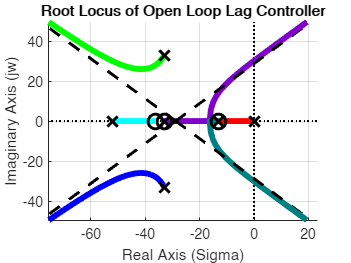

rla(D*G*H);
title("Root Locus of Open Loop Lag Controller")
hold off

nyqlog(D*G*H);

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


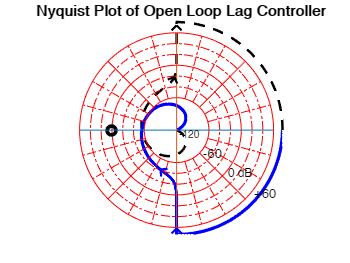

title("Nyquist Plot of Open Loop Lag Controller")
hold off

Ku = margin(D*G*H);
K = Ku/2

K = 293.8456


cltf = K*D*G/(1+K*D*G*H);
C2_T = cltf;

step(cltf)

% tune
z_t = sn_A+10

z_t = 23

D_t = 1/z_t*(s+z_t)/s;
Ku_t = margin(D_t*G*H);
K_t = Ku_t*0.2

K_t = 131.1299

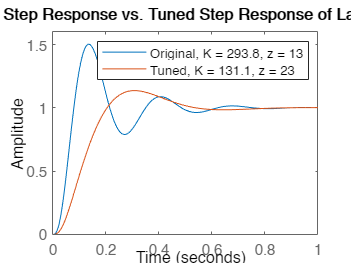

cltf_t = K_t*D_t*G/(1+K_t*D_t*G*H);
hold on
step(cltf_t)
title("Original Step Response vs. Tuned Step Response of Lag Controller")
legend("Original, K = 293.8, z = 13", "Tuned, K = 131.1, z = 23")
hold off

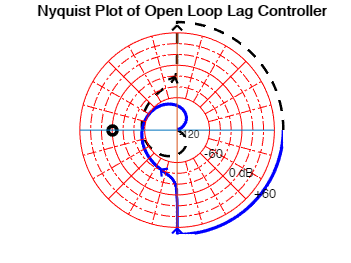

% position

hold off

rla(D*G*H/s)

ans = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0001i   0.0000 + 0.0001i   0.0000 + 0.0001i   0.0000 + 0.0001i   0.0000 + 0.0002i   0.0000 + 0.0002i   0.0000 + 0.0003i   0.0000 + 0.0003i   0.0000 + 0.0004i   0.0000 + 0.0005i   0.0000 + 0.0007i   0.0000 + 0.0008i   0.0000 + 0.0011i   0.0000 + 0.0014i   0.0001 + 0.0017i   0.0001 + 0.0022i   0.0002 + 0.0027i   0.0003 + 0.0034i   0.0005 + 0.0043i   0.0007 + 0.0053i   0.0011 + 0.0066i   0.0017 + 0.0082i   0.0026 + 0.0099i   0.0037 + 0.0120i   0.0052 + 0.0142i   0.0071 + 0.0166i   0.0093 + 0.0192i   0.0120 + 0.0220i   0.0151 + 0.0249i   0.0186 + 0.0280i   0.0224 + 0.0312i   0.0268 + 0.0347i   0.0315 + 0.0385i   0.0368 + 0.0426i   0.0426 + 0.0470i   0.0490 + 0.0518i   0.0561 + 0.0570i   0.0638 + 0.0627i
   0.0000 + 0.0000i   0.0000 - 

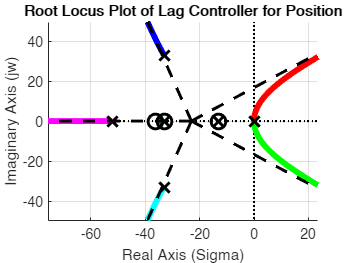

title("Root Locus Plot of Lag Controller for Position")
hold off

nyqlog(D*G*H/s)

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   2
=> Number of poles in RHP of closed-loop system:   2
=> Closed-loop-system is unstable


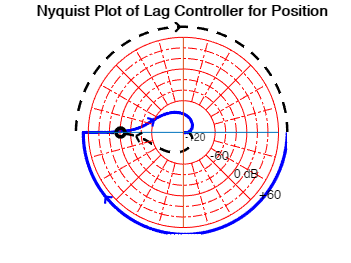

title("Nyquist Plot of Lag Controller for Position")
hold off


% putting zero at PXO/10
[Gm,Pm,Wcg,Wcp] = margin(D*G*H/s) % Pm = -0.77 deg -> put z at Px0/10

Gm = 0

Pm = -0.7701

Wcg = 0

Wcp = 0.2582

z_2 = 0.000000000001/10

z_2 = 1.0000e-13

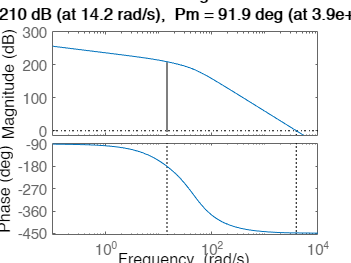


D_2 = 1/z_2*(s+z_2)/s;

margin(D_2*G*H/s);

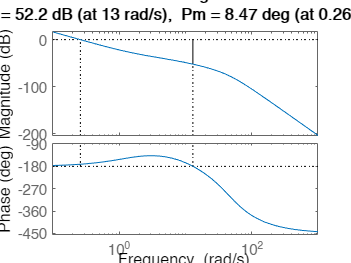


z_3 = 14.2/10;
D_3 = 1/z_3*(s+z_3)/s;

margin(D_3*G*H/s);

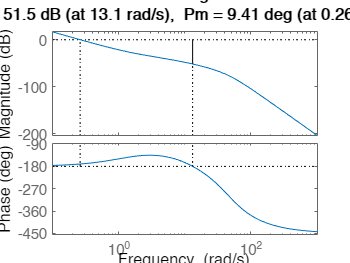

z_4 = 13/10;
D_4 = 1/z_4*(s+z_4)/s;
margin(D_4*G*H/s);

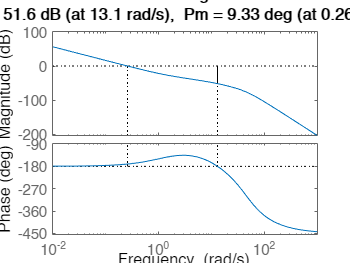


z_5 = 13.1/10;
D_5 = 1/z_5*(s+z_5)/s;
margin(D_5*G*H/s);

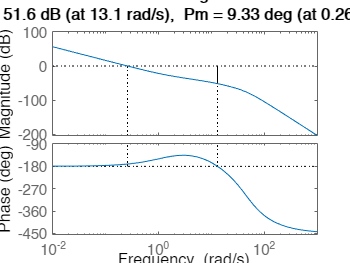

C3_z = z_5;

hold off

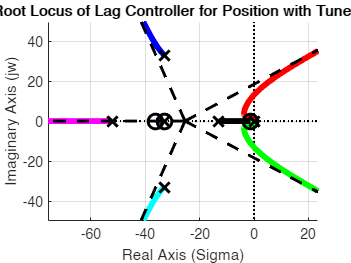

rla(D_5*G*H/s);
title("Root Locus of Lag Controller for Position with Tuned Z")
hold off

nyqlog(D_5*G*H/s);

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


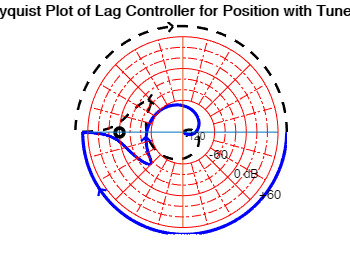

title("Nyquist Plot of Lag Controller for Position with Tuned Z")
hold off

% tune K
Ku_pos = margin(D_5*G*H/s)

Ku_pos = 379.9352

K_pos = Ku_pos/2

K_pos = 189.9676

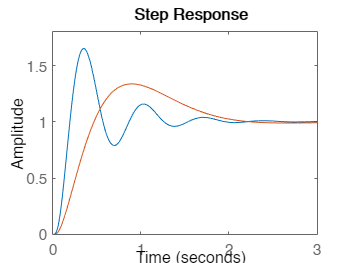

cltf_pos = K_pos*D_5*G/s/(1+K_pos*D_5*G*H/s);
hold off

step(cltf_pos);

K_pos_tuned = Ku_pos*0.15

K_pos_tuned = 56.9903

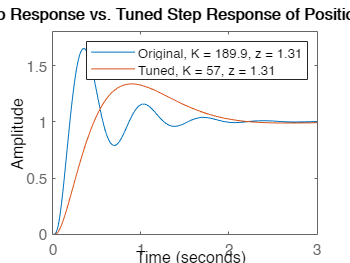

cltf_pos_tuned = K_pos_tuned*D_5*G/s/(1+K_pos_tuned*D_5*G*H/s);

hold on
step(cltf_pos_tuned);
title("Original Step Response vs. Tuned Step Response of Position Lag Controller")
legend("Original, K = 189.9, z = 1.31", "Tuned, K = 57, z = 1.31")
hold off